# **Workflow for Battery model comparison in BEV**

Copyright 2020-2021 The MathWorks, Inc.

## Overview

In the workflow we run the BEV example with battery models of different fidelity and use the data from hign fidelity models to get the parameters for the abstract model.

The models are run with over a same drive profile for the same duration, For this a "Drive cycle source" block is used from "Powertrain Blockset / Vehicle Scenario Builder" library, choose a appropriate drive cycle source from the list.

clearvars
disp('Start BEV battery plant model simulations workflow');

Start BEV battery plant model simulations workflow


driveCycle='FTP75'; % drive cycle type, choose from drive cycle source block in model
SimulationTime='2474'; % drive simulation time, put as per the drive cycle selection
coolantFlowfac=0.9;  %coolant flow rate factor
coolantTempDelt_K=-10;  %coolant temp delta with respect to ambient
ambTemp=293.15;   %ambient temp kelvin
batteryPowerRating_kW=[0 0 0]; % battery power rating for 
                                %[ Multi module pack, single module, basic battery]

There are three model fidelities available for battery with BEV setup. 

- Multi module battery pack

- Single battery module

- Basic battery 

For the example we create a battery  of ~400V

Battery power rating:

**AmpH * CellVolt * No.Of cells = Battery power rating**

## **Battery module **ssc_build 

To re build battery ssc block from library

startup_batteryExamplesProjectSetup;                                

## Multi module battery

The battery pack is made of multiple modules. For this 2 battery packs of 6 modules each are used. Each module for the example is of 16 cells in series and 2 in parallel, cell is pouch type  650 mm in height, 200 mm in width and 20 mm in thickness. Each module is in "Grouped" fidelity (read more [here](matlab:open('./html\batteryModuleDoc_parameterDefinition.html'))) and thermal look up table is used to model thermal behaviour.

The figures below shows the battery configuration,

The total number of cell in the battery pack comes to 96 series 4 parallel, which has a effective voltage of ~400 V. 

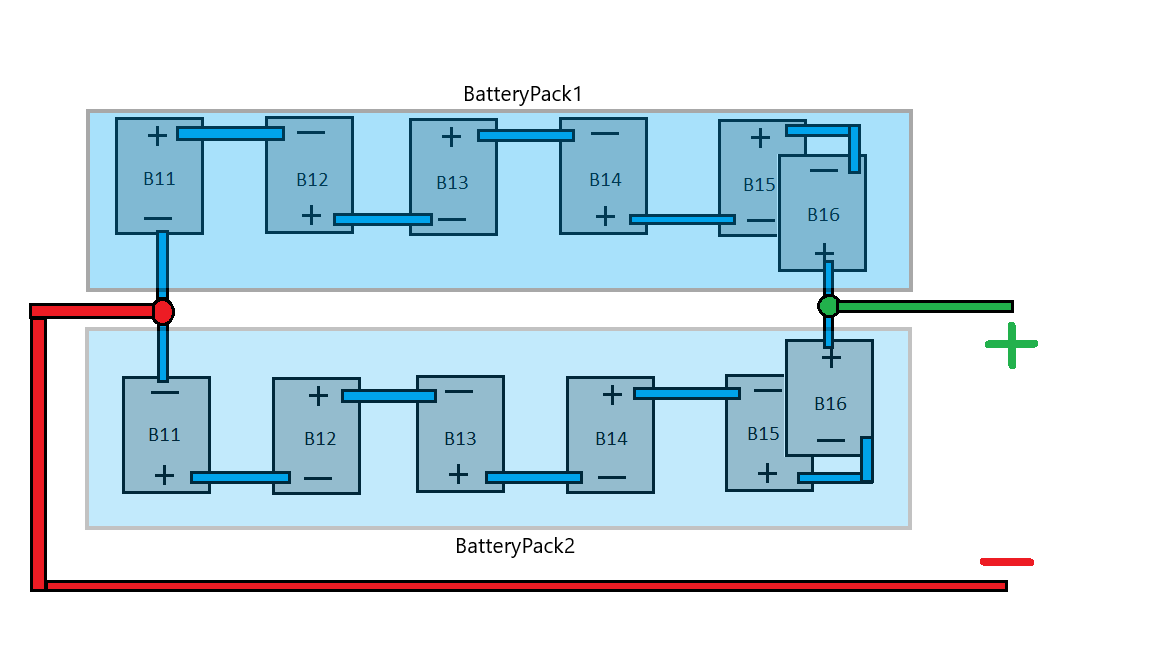

1-5 modules are on same plane and the 6th module is placed on top of the 5th module.The air gap between modules 1-2, 2-3, 3-4, 4-5 is 20mm and heat transfer happens between the modules, heat is also transferred between modules 5-6 through 20mm air gap. Top of the modules 1-4 is open to ambient, so is the positive plate of B11,B13 & B15 and negative plate of B12,B14 & B16. Bottom of module 1  to 5 and top of module 6 is connected to coolant and modeled using a look up table method. Parameters for thermal management is taken from detailed fidelity battery run in the battery module design [example](https://www.mathworks.com/matlabcentral/fileexchange/82330-battery-pack-design-solution-for-battery-evs-in-simscape).

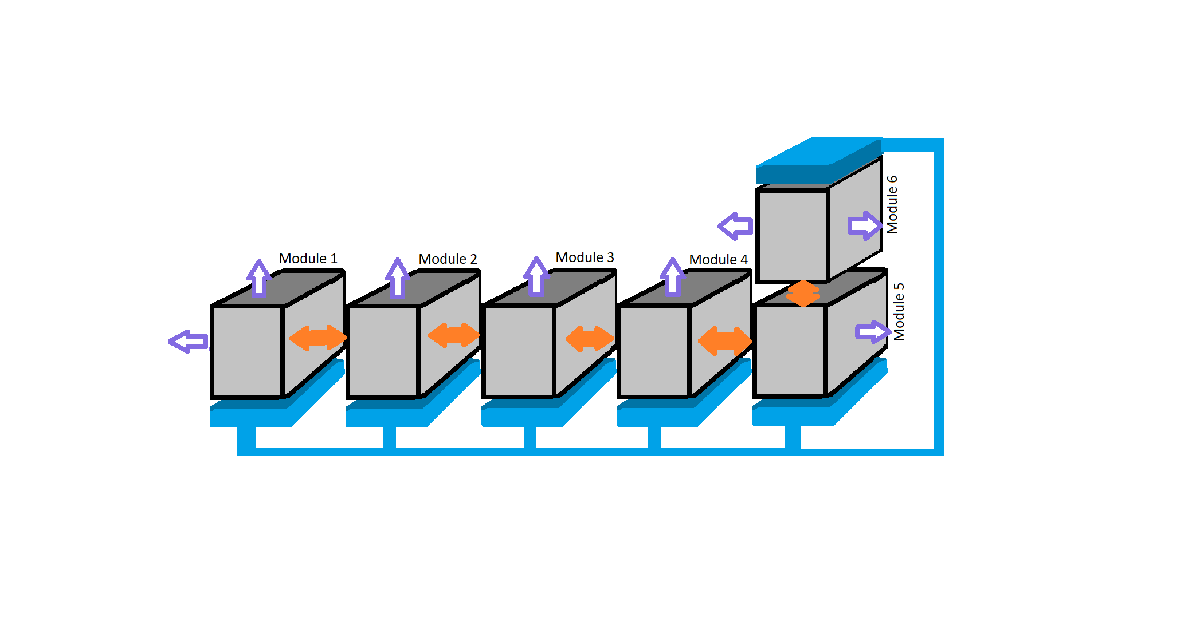

Model Name:*** BevDriveCycleModel***

Parameter file: BevDriveCycleModel***_params***

Battery reference: ***BatteryHVPackRefSub***

%Simulation of pack battery
% Open the model
open_system('BevDriveCycleModel.slx');

% Set the reference model for the detailed battery pack
% reference BatteryHVPackRefSub
% Load the parameters for the model
LoadMultimoduleBattery;

Configuring the BEV model with multi-module battery...



% set the Drive cycle for the "Drive cycle source" block
speedBlock=find_system('BevDriveCycleModel','Name','Drive Cycle Source');
set(getSimulinkBlockHandle(speedBlock),'cycleVar',driveCycle);

% Load the parameters for the workflow
load('BatteryHV_HTC_LUT.mat');
batteryHV1.batteryModuleBottomHTC=1*mat_cellQ;
batteryHV1.batteryCoolantHTC=1*mat_cellQ;
batteryHV2.batteryModuleBottomHTC=1*mat_cellQ;
batteryHV2.batteryCoolantHTC=1*mat_cellQ;
batteryHV.batteryCoolantFlwR=coolantFlowfac; % Coolant flow rate factor
batteryHV.batteryCoolantFlwT=coolantTempDelt_K; % Coolant temperature delta wrt. ambient
batteryHV.AmbTemp=ambTemp;

% Run the simulation for the specified Simulation time
simoutPack=sim('BevDriveCycleModel','StopTime',SimulationTime);
timeDetailed=simoutPack.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;

Battery power rating for pack:

**battery rating***** = *****battery rating***** of pack 1 + *****battery rating***** of pack 2***

batteryPowerRating_kW(1) = median(batteryHV1.batteryCapacity_LUT)*batteryHV1.battery_N_cells*6 ...
    *median(median(batteryHV1.batteryEm_LUT)) + median(batteryHV2.batteryCapacity_LUT) ... 
    *batteryHV2.battery_N_cells*6*median(median(batteryHV2.batteryEm_LUT));

## Single module battery

The battery is a single battery module of 108 cells in series and 4 in parallel. Battery module is in grouped fidelity.

Model Name:*** BevDriveCycleModel***

Parameter file: ***BevDriveCycleModularBattery_params***

Battery reference: ***BatteryHighGroupedRefSub***

The parameters for single module are loaded from the multimodule battery pack , restructured to the dimensions required in battery modules.

%% Simulation for single module
open_system('BevDriveCycleModel.slx');

% Set the reference model for the detailed battery pack
% reference BatteryHighGroupedRefSub
% Load the parameters for the model
LoadSinglemoduleBattery;

Configuring the BEV model with grouped-single-module battery...



% set the Drive cycle for the "Drive cycle source" block
speedBlock=find_system('BevDriveCycleModel','Name','Drive Cycle Source');
set(getSimulinkBlockHandle(speedBlock),'cycleVar',driveCycle);

% Load the parameters for the workflow
batteryHV.batteryCoolantHTC=repmat(batteryHV1.batteryCoolantHTC,1,1,12);
batteryHV.batteryCoolantFlwR=coolantFlowfac; % Coolant flow rate factor
batteryHV.batteryCoolantFlwT=coolantTempDelt_K; % Coolant temperature delta wrt. ambient
batteryHV.AmbTemp=ambTemp;


% Run the simulation for the specified Simulation time
simoutModule=sim('BevDriveCycleModel','StopTime',SimulationTime);
timeModule=simoutModule.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;

Battery power rating for pack:

**battery rating***** = cell Ahr * cell voltage * number of cell***

batteryPowerRating_kW(2) = median(batteryHV.batteryCapacity_LUT)*batteryHV.battery_N_cells ...
    *median(median(batteryHV.batteryEm_LUT));

## Basic battery

The power source is a constant DC voltage source which can supply any current demand from it. There is no thermal computaion and SoC estimation. 

Constant voltage for the setup is set as the same level as the detailed model.

%% Simulation for simple battery
% Open the model
open_system('BevDriveCycleModel.slx');

% Set the reference model for the detailed battery pack
% reference BatteryHighGroupedRefSub
% Load the parameters for the model
LoadBasicBattery;

Configuring the BEV model with all basic components...



% Set the drive cycle for the drive cycle source block
controlBlock=find_system('BevDriveCycleModel','Name', ...
    'Driver & Environment');
set(getSimulinkBlockHandle(controlBlock),'ReferencedSubsystem', ...
    'DirectDriveCycleRefSub');
speedBlock=find_system('BevDriveCycleModel','Name','Drive Cycle Source');
set(getSimulinkBlockHandle(speedBlock),'cycleVar',driveCycle);

% Set the battery voltage same as detailed battery and compute internal
% resistance from Pack current voltage data
batteryHV.packVoltage_V=simoutPack.logsout.get("Volt").Values.Data(1);
voltDiff=abs(batteryHV.packVoltage_V-simoutPack.logsout.get("Volt").Values.Data);
packCurr=simoutPack.logsout.get("Current").Values.Data;
for Idx=1:size(packCurr,1)
    if packCurr(Idx)<1
        voltDiff(Idx)=0;
    end
end
intR=voltDiff./packCurr;
batteryHV.internal_R_Ohm= mean(intR);

%Initial value for battery capacity and SoC
initial.hvBatteryCharge_Ah=max(batteryHV.batteryCapacity_LUT)...
        *batteryHV.batteryNp;
initial.hvBatterySOC_pct=batteryHV.battery_SOC_init;

% Simulate the model
simoutBasic=sim('BevDriveCycleModel','StopTime',SimulationTime);
timeBasic=simoutBasic.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;

bdclose('BevDriveCycleModel.slx');

Battery power rating for the basic battery is very high, it can supply any current demande from it.

batteryPowerRating_kW(3)=999999; % dummy value 

## Plotting

Plot of battery current, voltage and temperature for different battery model fidelity for analysis. Red for battery with multi modules, Blue for single module battery and Green for basic battery.

Since the battery temperature is not active for basic battery, for comparison we take the temperature as the ambient temperature.

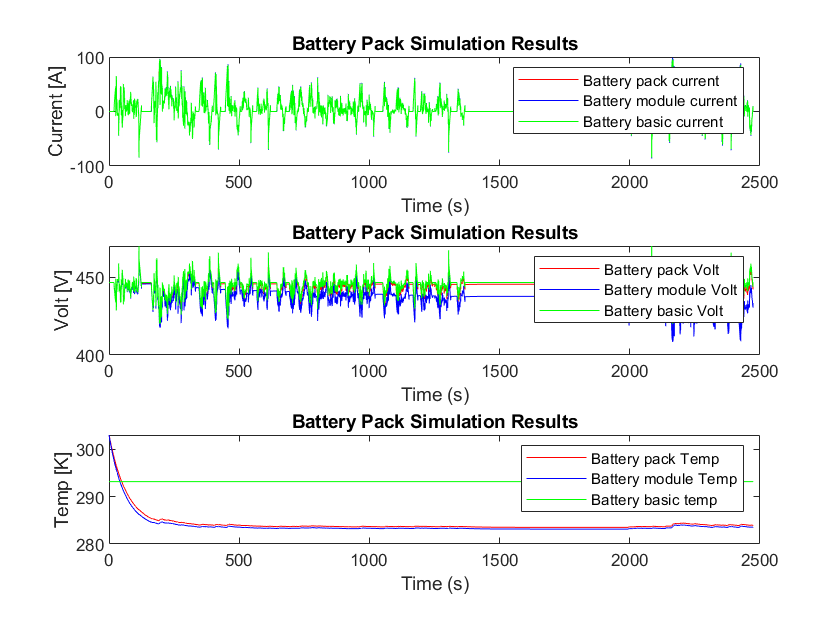

%% Plot for comparison
% Plot for current
figure
simlog_handles(1) = subplot(3, 1, 1);
plot(simoutPack.logsout.get("Current").Values,'r-')
hold on
plot(simoutModule.logsout.get("Current").Values  ,'b-')
plot(simoutBasic.logsout.get("Current").Values  ,'g-')
hold off
legend('Battery pack current','Battery module current','Battery basic current')
xlabel('Time (s)')
ylabel('Current [A]')
%
title('Battery Pack Simulation Results')

%% Plot for Volt
simlog_handles(2) = subplot(3, 1, 2);
plot(simoutPack.logsout.get("Volt").Values,'r-')
hold on
plot(simoutModule.logsout.get("Volt").Values  ,'b-')
plot(simoutBasic.logsout.get("Volt").Values  ,'g-')
hold off
legend('Battery pack Volt','Battery module Volt','Battery basic Volt')
xlabel('Time (s)')
ylabel('Volt [V]')
%
title('Battery Pack Simulation Results')

%% Plot for Temp
simlog_handles(3) = subplot(3, 1, 3);
plot(simoutPack.logsout.get("Temp").Values,'r-')
hold on
plot(simoutModule.logsout.get("Temp").Values  ,'b-')
plot([0,str2double(SimulationTime)],[ambTemp,ambTemp],'g-')
hold off
legend('Battery pack Temp','Battery module Temp','Battery basic temp')
xlabel('Time (s)')
ylabel('Temp [K]')
%
title('Battery Pack Simulation Results')